res1=[5.08 2.441;7.41 1.112;10.00 0.00;12.42 -0.805;15.18 -1.540;17.32 -1.999;19.31 -2.378];
res2=[5.09 14.29;7.40 7.45;10.00 -0.0041;12.42 -4.94;15.16 -9.15;17.32 -11.68;19.33 -13.43];
res1(:,1)=res1(:,1)-10;
res2(:,1)=res2(:,1)-10;

k=sum(res1(:,2).*res2(:,2))/sum(res1(:,2).^2)

k = 5.8654

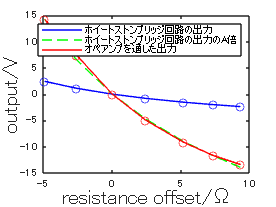

plot(res1(:,1),res1(:,2), 'b')
hold on
plot(res1(:,1),res1(:,2)*k, 'g--')
plot(res2(:,1),res2(:,2), 'r')
plot(res1(:,1),res1(:,2), 'ob')
plot(res2(:,1),res2(:,2), 'ro')
legend("ホイートストンブリッジ回路の出力", "ホイートストンブリッジ回路の出力のA倍", "オペアンプを通した出力")
xlabel("resistance offset/Ω", 'FontSize', 15)
ylabel("output/V", 'FontSize', 15)
hold off

plot(res1(:,1),res1(:,2), 'b')
hold on
y(:,1)=res1(:,1)

y =    -4.9200    1.8450
   -2.5900    0.9712
         0         0
    2.4200   -0.9075
    5.1800   -1.9425
    7.3200   -2.7450
    9.3100   -3.4912


y(:,2)=arrayfun(@(x) -15/(4*10)*x, res1(:,1))

y =    -4.9200    1.8450
   -2.5900    0.9712
         0         0
    2.4200   -0.9075
    5.1800   -1.9425
    7.3200   -2.7450
    9.3100   -3.4912


y2(:,1)=res1(:,1)

y2 =    -4.9200    2.4469
   -2.5900    1.1157
         0         0
    2.4200   -0.8095
    5.1800   -1.5429
    7.3200   -2.0095
    9.3100   -2.3823


R=10

R = 10

y2(:,2)=arrayfun(@(x) 15*(1/2-(R+x)/(2*R+x)), res1(:,1))

y2 =    -4.9200    2.4469
   -2.5900    1.1157
         0         0
    2.4200   -0.8095
    5.1800   -1.5429
    7.3200   -2.0095
    9.3100   -2.3823


y3(:,1)=res1(:,1)

y3 =    -4.9200    2.1865
   -2.5900    1.0910
         0         0
    2.4200   -0.8001
    5.1800   -1.4776
    7.3200   -1.8653
    9.3100   -2.1419


R=10

R = 10

y3(:,2)=arrayfun(@(x) -15*(R/(4*R*R+4*R*x+x*x)*x+R*(4*R+2*x)/2/(4*R*R+4*R*x+x*x).^2*x*x), res1(:,1))

y3 =    -4.9200    2.1865
   -2.5900    1.0910
         0         0
    2.4200   -0.8001
    5.1800   -1.4776
    7.3200   -1.8653
    9.3100   -2.1419


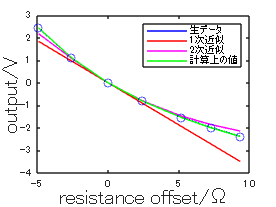

plot(y(:,1),y(:,2),'r')
plot(y2(:,1),y3(:,2),'m')
plot(y2(:,1),y2(:,2),'g')
plot(res1(:,1),res1(:,2), 'bo')
legend('生データ','1次近似','2次近似','計算上の値')
xlabel("resistance offset/Ω", 'FontSize', 15)
ylabel("output/V", 'FontSize', 15)
hold off